clear;clc;

addpath(genpath('/Users/lyys/MyDocs/repos_from_github/gkaModelEye'))


sg_1center=createSceneGeometry()

sg_1center = struct with fields:
    cameraIntrinsic: [1×1 struct]
     cameraPosition: [1×1 struct]
     screenPosition: [1×1 struct]
                eye: [1×1 struct]
         refraction: [1×1 struct]
               meta: [1×1 struct]


sg_1center.eye.rotationCenters.ele=[-12,0,0];
sg_1center.eye.rotationCenters.azi=[-12,0,0];

eyePose=[40,-30,0,3]

eyePose =     40   -30     0     3


% renderEyePose(eyePose,sg_1center,'showPupilTextLabels',true,'showAzimuthPlane',true,'nStopPerimPoints',20)

% poses={[10,10,0,3],[20,20,0,3],[0,20,0,3]}

% 1 axis incremental
% poses={[0,5,0,3],[0,10,0,3],[0,15,0,3],[0,20,0,3]}
% poses={[0,30,0,3],[0,40,0,3],[0,50,0,3],[0,60,0,3]}

% 4 directions
% poses={[20,20,0,3],[20,-20,0,3],[-20,-20,0,3],[-20,20,0,3]}
poses={[40,40,0,3],[40,-40,0,3],[-40,-40,0,3],[-40,40,0,3]}

poses = 1×4 cell array
    {[40 40 0 3]}    {[40 -40 0 3]}    {[-40 -40 0 3]}    {[-40 40 0 3]}


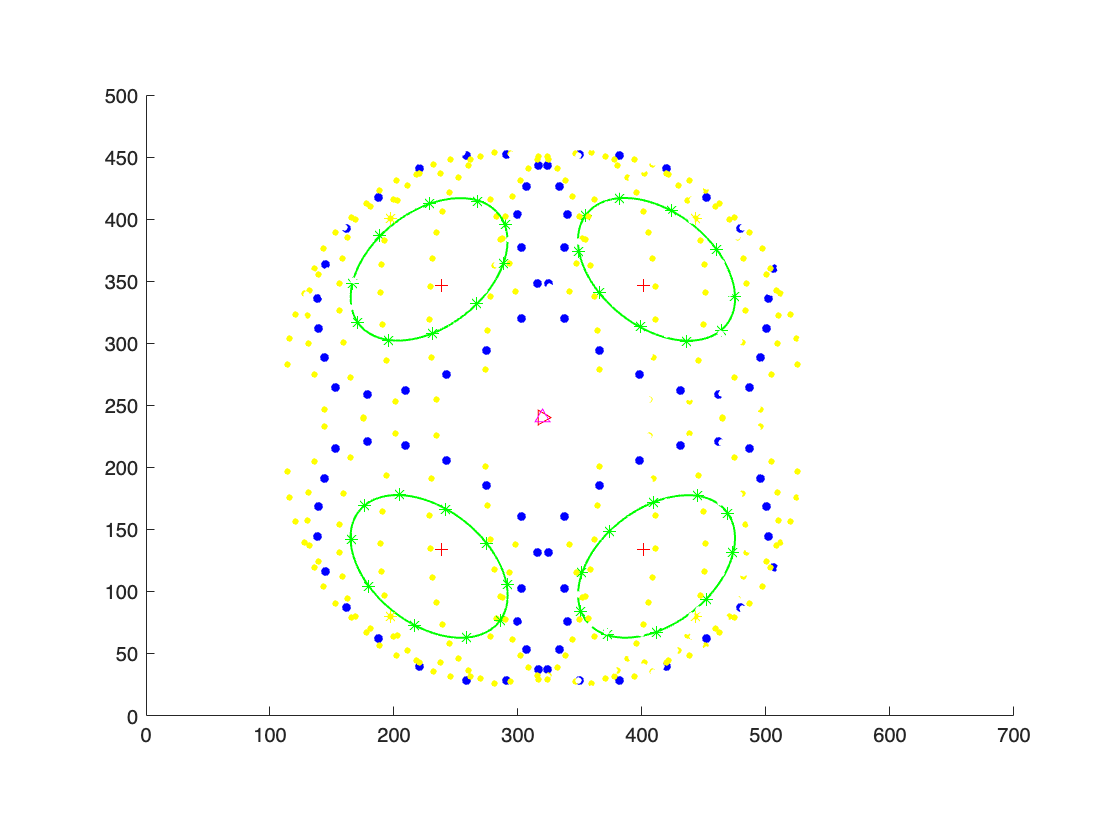

figure;
I = cell(1,9);
daspect([1 1 1])
% axis equal
for pp = 1:length(poses)
    % Obtain the rendering of the model for this pose
    [figHandle, ~, renderedFrame] = renderEyePose(poses{pp}, sg_1center, 'newFigure',false,'nStopPerimPoints',10);
    % close(figHandle)
    % I{pp}=insertText(renderedFrame.cdata,[20 20],sprintf('[%d, %d, %d, %d]',poses(pp,:)),'FontSize',30,'BoxColor','white');
end


out_ellipse=[];
rotation_centers_azi=[];
rotation_centers_ele=[];
for i=1:length(poses)
    [elli_params_temp,~,image_points,~,~,~,point_labels]=projectModelEye(poses{i},sg_1center,'nStopPerimPoints',100,'fullEyeModelFlag',true);
    out_ellipse(i,:)=ellipse_transparent2ex(elli_params_temp);
    rotation_centers_azi(i,:)=image_points(find(strcmp(point_labels, 'aziRotationCenter')),:);
    rotation_centers_ele(i,:)=image_points(find(strcmp(point_labels, 'eleRotationCenter')),:);
end

names={'cx','cy','a','b','theta','rot_center_azi_x','rot_center_azi_y','rot_center_ele_x','rot_center_ele_y'};
table2write=table(out_ellipse(:,1),out_ellipse(:,2),out_ellipse(:,3),out_ellipse(:,4),out_ellipse(:,5),rotation_centers_azi(:,1),rotation_centers_azi(:,2),rotation_centers_ele(:,1),rotation_centers_ele(:,2),'VariableNames',names)

table2write = 4×9 table
      cx        cy        a        b        theta     rot_center_azi_x    rot_center_azi_y    rot_center_ele_x    rot_center_ele_y
    ______    ______    _____    ______    _______    ________________    ________________    ________________    ________________

    411.73    120.21    71.74    46.506    0.66668          320                 240                 320                 240       
    411.71    359.78    72.02    46.312     2.4728          320                 240                 320                 240       
    228.27    359.79    71.74    46.506    0.66668          320                 240                 320                 240       
    228.29    

point_labels

point_labels = 785×1 cell array
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}
    {'stopPerimeter'}




write_path="/Users/lyys/MyDocs/repos/eyeball_translation/using_gkaModelEye/";
% writematrix(ellipse_transparent2ex(pupil_ellipse_params),write_path+"test.csv")
writetable(table2write,write_path+"table1.csv")
